# Dự đoán kết quả tốt nghiệp của sinh viên khóa 06 dựa vào khóa 03, 04, 05

openExample('nnet/PlotConfusionMatrixUsingCategoricalLabelsExample')

Qui trình thực hiện:

Load the data consisting of synthetic images of handwritten digits. `XTrain` is a 28-by-28-by-1-by-5000 array of images and `YTrain` is a categorical vector containing the image labels.

openExample('nnet/PlotConfusionMatrixUsingCategoricalLabelsExample')

openExample('C:\Users\HT\Desktop\List_IT\DoAn_DuDoan_XepHang_TotNghiep\Demo')

## Giai đoạn 1: Tải dữ liệu thư mục lên matlab 

- Mở tiệp dữ liệu (.csv) excel 

data = readtable('DSSV_3K.csv');
Data = table2array(data);
whos Data

  Name        Size             Bytes  Class     Attributes

  Data      530x52            220480  double              



- Lấy dữ liệu cột phân lớp xếp loại cho vào y (nghĩa là cột cuối cùng)

y = Data(:,size(Data,2));
whos y

  Name        Size            Bytes  Class     Attributes

  y         530x1              4240  double              



- Lấy dữ liệu các cột điểm môn học cho vào x (trừ cột phân lớp cuối cùng)

x = Data(:,1:(size(Data,2)-1));
whos x

  Name        Size             Bytes  Class     Attributes

  x         530x51            216240  double              



Datadao = (Data(:,1:10))';
[minData, vitri] = min(Datadao);
%min_Data = min(min(Data(:,1:10)))
Col_ko_tichluy_tc=minData'

Col_ko_tichluy_tc =     3.8000
    4.1000
    4.7000
    4.0000
    3.6000
    3.5000
    4.4000
    3.6000
    3.8000
    3.5000


Data_rutgon=[Col_ko_tichluy_tc,Data(:,11:size(Data,2))]

Data_rutgon =     3.8000    3.6000    4.3000    3.1000    5.8000    3.1000    5.5000    3.4000    5.5000    5.1000    5.4000    4.1000    6.5000    5.4000    6.4000    4.1000    6.0000    5.9000    5.7000    5.0000    2.9000    6.2000    6.2000    6.4000    5.6000    6.9000    3.1000    7.0000    3.6000    5.7000    4.0000    4.5000    7.6000    4.7000    7.0000    7.1000    6.6000    4.1000    7.5000    5.4000    2.8000    3.2000         0
    4.1000    5.1000    7.7000    4.9000    5.4000    5.2000    6.2000    3.3000    2.7000    6.7000    3.2000    4.5000    4.2000    5.0000    6.3000    6.8000    4.7000    4.5000    5.1000    5.3000    4.4000    6.1000    5.1000    5.0000    4.7000    4.8000    4.5000    3.8000    6.6000    6.7000    6.9000    4.8000    6.3000    6.7000    4.6000    6.2000    6.1000    6.1000    4.3000    3.6000    5.5000    3.6000         0
    4.7000    3.6000    6.5000    4.7000    7.1000    2.6000    5.8000    4.4000    5.1000    6.7000    5.2000    2.9000    

%A=1; 
%A + " sinhvien"

## **Giai đoạn 2: Tiền xử lý dữ liệu**

- Phân từng loại sinh viên ra từng danh sách riêng theo {0...4}<=>{Không đạt =>Xuất sắc} 

%[MData0,MData1,MData2,MData3,MData4] = DivideFollow5Label(Data_rutgon);
[MData0,MData1,MData2,MData3,MData4] = DivideFollow5Label(Data);

- Trộn dữ liệu 10 lần trước khi train

MData0_shuffled = Shuffled(MData0,10);
MData1_shuffled = Shuffled(MData1,10);
MData2_shuffled = Shuffled(MData2,10);
MData3_shuffled = Shuffled(MData3,10);
MData4_shuffled = Shuffled(MData4,10);

- Lấy 70% để train và 30% để test

[MData0_shuffled_train,MData0_shuffled_test]=Splitbypercentage(MData0_shuffled,0.7);
[MData1_shuffled_train,MData1_shuffled_test]=Splitbypercentage(MData1_shuffled,0.7);
[MData2_shuffled_train,MData2_shuffled_test]=Splitbypercentage(MData2_shuffled,0.7);
[MData3_shuffled_train,MData3_shuffled_test]=Splitbypercentage(MData3_shuffled,0.7);
[MData4_shuffled_train,MData4_shuffled_test]=Splitbypercentage(MData4_shuffled,0.7);

- Gom tất cả các loại xếp hạng thành một train và test chung

MData_shuffled_train = [MData0_shuffled_train;MData1_shuffled_train;MData2_shuffled_train;MData3_shuffled_train;MData4_shuffled_train];
MData_shuffled_test = [MData0_shuffled_test;MData1_shuffled_test;MData2_shuffled_test;MData3_shuffled_test;MData4_shuffled_test];
whos MData_shuffled_train

  Name                        Size             Bytes  Class     Attributes

  MData_shuffled_train      371x52            154336  double              



whos MData_shuffled_test

  Name                       Size            Bytes  Class     Attributes

  MData_shuffled_test      159x52            66144  double              



- Lấy cột (cuối cùng) phân lớp xếp loại ra để so sánh, kiểm tra sau khi huấn luyện

y_mtrain = MData_shuffled_train(:,size(MData_shuffled_train,2));
y_mtest = MData_shuffled_test(:,size(MData_shuffled_test,2));
whos y_mtest

  Name           Size            Bytes  Class     Attributes

  y_mtest      159x1              1272  double              



- Loại cột phân lớp ra để dự đoán sau khi huấn luyện phân lớp trong mô hình học có giám sát SVM, KNN và Tree

MDataS_train = MData_shuffled_train(:,1:(size(MData_shuffled_train,2)-1));
MDataS_test = MData_shuffled_test(:,1:(size(MData_shuffled_test,2)-1));
whos MDataS_test

  Name               Size            Bytes  Class     Attributes

  MDataS_test      159x51            64872  double              



## **Giai đoạn 3.1: Chạy các thuật toán học có giám sát trên 2 phân lớp**

Chuyển các phân lớp {0...4} sang {0,1} trong đó:

    0: Không đậu tốt nghiệp

    1: Đậu tốt nghiệp (gồm những sinh viên có học lực: Trung bình, Khá, Giỏi và Xuất sắc)

%% Standardize Data
%-Chuan hoa cot phan lop du lieu theo chuan {0,1} (khong dau, co dau)
y_train = StandardizeColTo1and0(y_mtrain,1);
y_test = StandardizeColTo1and0(y_mtest,1);

    Cho data vào chung

Datatrain = [MDataS_train,y_train];
Datatest = [MDataS_test,y_test];

**        1.  SVM(SMO)**

%% Run algorithm SMO (SVM)
%-Su dung thuat toan SMO (SVM)
%-1. Dua datatrain de may hoc
SVMModel = fitcsvm(MDataS_train,y_train);
%-2. Dua datatest de may test
SVMtest = predict(SVMModel,MDataS_test);
%-3. So sanh ket qua may du doan voi ket qua goc
ResultTrueSVM = sum(SVMtest == y_test)

ResultTrueSVM = 159

%-Do chinh xac cua thuat toan phan lop
AccuracySVM = ResultTrueSVM * 100 / size(y_test,1)

AccuracySVM = 100


%-Confusion matrix table cho SMO (SVM) sau khi may du doan xong
%- Tao bang confusion
TableSVM = CreateConfusionTable(SVMtest,y_test)

TableSVM = 3×4 cell array
    {["Yes"]}    {["No"]}    {["ClassDistribute"]}    {0×0 double}
    {[  119]}    {[   0]}    {["Yes_test = 1"   ]}    {[     119]}
    {[    0]}    {[  40]}    {["No_test = 0"    ]}    {[      40]}


**        2.  C4.5(J4.8)**

%% Run algorithm J48 (C4.5)
%-Su dung thuat toan J48 (C4.5)
%-1. Dua datatrain de may hoc
TreeModel = fitctree(MDataS_train,y_train);
%-2. Dua datatest de may test
Treetest = predict(TreeModel,MDataS_test);
%-3. So sanh ket qua may du doan voi ket qua goc
ResultTrueTree = sum(Treetest == y_test)

ResultTrueTree = 152

%-Do chinh xac cua thuat toan phan lop
AccuracyTree = ResultTrueTree * 100 / size(y_test,1)

AccuracyTree = 95.5975


%-Confusion matrix table cho J48 (C4.5) sau khi may du doan xong
%- Tao bang confusion
TableTree = CreateConfusionTable(Treetest,y_test)

TableTree = 3×4 cell array
    {["Yes"]}    {["No"]}    {["ClassDistribute"]}    {0×0 double}
    {[  117]}    {[   2]}    {["Yes_test = 1"   ]}    {[     119]}
    {[    5]}    {[  35]}    {["No_test = 0"    ]}    {[      40]}


**        3.  KNN(IBk)**

%% KNN
%-Su dung thuat toan KNN (IBk)
%-1. Dua datatrain de may hoc
trainKNN = fitcknn(MDataS_train,y_train);
%-2. Dua datatest de may test
label = predict(trainKNN,MDataS_test);
%-3. So sanh ket qua may du doan voi ket qua goc
ResultTrueKNN = sum(label == y_test)

ResultTrueKNN = 158

%-Do chinh xac cua thuat toan phan lop
AccuracyKNN = ResultTrueKNN * 100 / size(y_test,1)

AccuracyKNN = 99.3711

%- Tao bang confusion
TableKNN = CreateConfusionTable(label,y_test)

TableKNN = 3×4 cell array
    {["Yes"]}    {["No"]}    {["ClassDistribute"]}    {0×0 double}
    {[  119]}    {[   0]}    {["Yes_test = 1"   ]}    {[     119]}
    {[    1]}    {[  39]}    {["No_test = 0"    ]}    {[      40]}


## **Giai đoạn 3.2: Chạy các thuật toán học có giám sát trên nhiều phân lớp**

- Sử dụng APPS trong matlab

**        1.  SVM(SMO)**

- Trainning

%yfit = trainedModelSVM.predictFcn(DataS_test);
yfit = trainedModel.predictFcn(MDataS_test);
ResultTrue_MultiSVM = sum(yfit == y_mtest)

ResultTrue_MultiSVM = 159

Accuracy_MultiSVM = ResultTrue_MultiSVM * 100 / size(y_mtest,1)

Accuracy_MultiSVM = 100

- Ma trận nhầm lẫn(Confusion matrix)

%Matrix
%Ma trận chuyển vị
Ytest=y_mtest' + 1;
Yfit=yfit' + 1;

%Có bao nhiêu giá trị trong ma trận
%m=unique(Ytest);
%n=unique(Yfit);

%Chỉ số
A=size(Ytest,2);
M=size(unique(Ytest),2);

B=size(Yfit,2);
N=size(unique(Yfit),2);

%Tạo ma trận zeros thỏa các chỉ số trên
targets = zeros(M,A);
outputs = zeros(N,B);

%Xuất vị trí ma trận đúng thứ tự
targetsIdx = sub2ind(size(targets), Ytest, 1:A);
outputsIdx = sub2ind(size(outputs), Yfit, 1:B);

%So sánh
targets(targetsIdx) = 1;
outputs(outputsIdx) = 1;

%Tạo bảng ma trận
Table_MultiSVM = plotconfusion(outputs,targets)

Table_MultiSVM =   Figure (PLOTCONFUSION1) with properties:

      Number: 1
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [383 84 600 600]
       Units: 'pixels'

  Show all properties


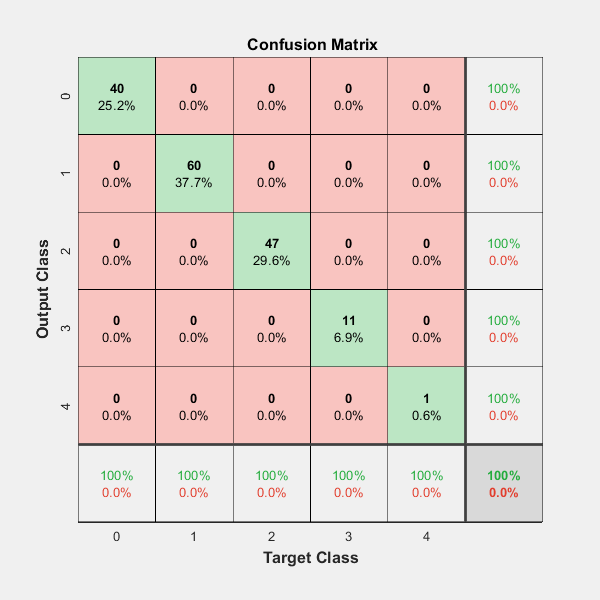


%Chỉnh nhãn trong plotconfusion
h = gca;
h.XTickLabel = {'0','1','2','3','4',''};
h.YTickLabel = {'0','1','2','3','4',''};
h.YTickLabelRotation = 90;
h.XTickLabelRotation = 0;

**        2.  C4.5(J4.8)**

- Trainning

%yfit = trainedModelC45.predictFcn(DataS_test);
%yfit = trainedModel.predictFcn(MDataS_test);
yfit1 = trainedModel1.predictFcn(MDataS_test);
ResultTrue_MultiC45 = sum(yfit1 == y_mtest)

ResultTrue_MultiC45 = 145

Accuracy_MultiC45 = ResultTrue_MultiC45 * 100 / size(y_mtest,1)

Accuracy_MultiC45 = 91.1950

- Ma trận nhầm lẫn(Confusion matrix)

%Matrix
%Ma trận chuyển vị
Ytest=y_mtest' + 1;
Yfit1=yfit1' + 1;

%Có bao nhiêu giá trị trong ma trận
%m=unique(Ytest);
%n=unique(Yfit1);

%Chỉ số
A=size(Ytest,2);
M=size(unique(Ytest),2);

B=size(Yfit1,2);
N=size(unique(Yfit1),2);

%Tạo ma trận zeros thỏa các chỉ số trên
targets = zeros(M,A);
outputs = zeros(N,B);

%Xuất vị trí ma trận đúng thứ tự
targetsIdx = sub2ind(size(targets), Ytest, 1:A);
outputsIdx = sub2ind(size(outputs), Yfit1, 1:B);

%So sánh
targets(targetsIdx) = 1;
outputs(outputsIdx) = 1;

%Tạo bảng ma trận
Table_MultiC45 = plotconfusion(outputs,targets)

Table_MultiC45 =   Figure (PLOTCONFUSION1) with properties:

      Number: 1
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [383 84 600 600]
       Units: 'pixels'

  Show all properties


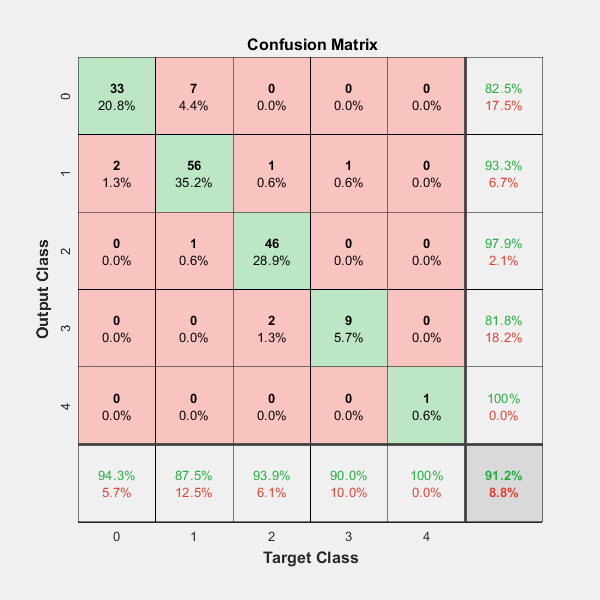


%Chỉnh nhãn trong plotconfusion
h = gca;
h.XTickLabel = {'0','1','2','3','4',''};
h.YTickLabel = {'0','1','2','3','4',''};
h.YTickLabelRotation = 90;
h.XTickLabelRotation = 0;

**        3.  KNN(IBk)**

- Trainning

%yfit = trainedModelKNN.predictFcn(DataS_test);
%yfit = trainedModel.predictFcn(MDataS_test);
yfit2 = trainedModel2.predictFcn(MDataS_test);
ResultTrue_MultiKNN = sum(yfit2 == y_mtest)

ResultTrue_MultiKNN = 157

Accuracy_MultiKNN = ResultTrue_MultiKNN * 100 / size(y_mtest,1)

Accuracy_MultiKNN = 98.7421

- Ma trận nhầm lẫn(Confusion matrix)

%Matrix
%Ma trận chuyển vị
Ytest=y_mtest' + 1;
Yfit2=yfit2' + 1;

%Có bao nhiêu giá trị trong ma trận
%m=unique(Ytest);
%n=unique(Yfit2);

%Chỉ số
A=size(Ytest,2);
M=size(unique(Ytest),2);

B=size(Yfit2,2);
N=size(unique(Yfit2),2);

%Tạo ma trận zeros thỏa các chỉ số trên
targets = zeros(M,A);
outputs = zeros(N,B);

%Xuất vị trí ma trận đúng thứ tự
targetsIdx = sub2ind(size(targets), Ytest, 1:A);
outputsIdx = sub2ind(size(outputs), Yfit2, 1:B);

%So sánh
targets(targetsIdx) = 1;
outputs(outputsIdx) = 1;

%Tạo bảng ma trận
Table_MultiKNN = plotconfusion(outputs,targets)

Table_MultiKNN =   Figure (PLOTCONFUSION1) with properties:

      Number: 1
        Name: 'Confusion (plotconfusion)'
       Color: [0.9400 0.9400 0.9400]
    Position: [383 84 600 600]
       Units: 'pixels'

  Show all properties


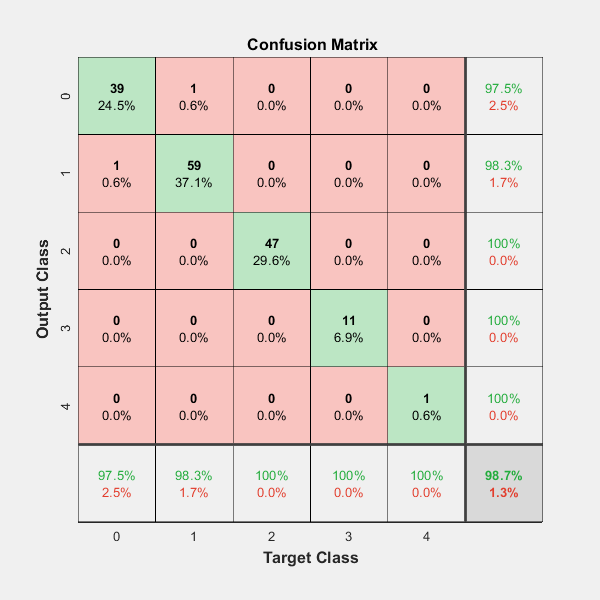


%Chỉnh nhãn trong plotconfusion
h = gca;
h.XTickLabel = {'0','1','2','3','4',''};
h.YTickLabel = {'0','1','2','3','4',''};
h.YTickLabelRotation = 90;
h.XTickLabelRotation = 0;

## Giai đoạn 4: Kiểm tra trên weka

- Xuất file .arff để chạy trên weka

- TH1: Kiểm tra trên 2 phân lớp: Dự đoán khả năng tốt nghiệp của một sinh viên

arffwrite("C:\Users\HT\Desktop\DuDoan_TotNghiep_train",Datatrain);
arffwrite("C:\Users\HT\Desktop\DuDoan_TotNghiep_test",Datatest);

- TH2: Kiểm tra trên nhiều phân lớp: Dự đoán khả năng xếp loại tốt nghiệp của một sinh viên

arffwrite("C:\Users\HT\Desktop\DuDoan_KetQuaTotNghiep_train",MData_shuffled_train);
arffwrite("C:\Users\HT\Desktop\DuDoan_KetQuaTotNghiep_test",MData_shuffled_test);

(Giai đoạn này làm việc chủ yếu trên weka để xem matlab dự đoán có chính xác không?)

## Giai đoạn 5: Dự đoán danh sách sinh viên khóa 06

%Du doan danh sach sinh vien khoa 06 thong qua thuat toan SVM
%Vì có dự đoán tỉ lệ cao nhất
dhth06 = readtable('06DHTH.csv');
DHTH06 = table2array(dhth06);

Dự đoán tốt nghiệp

SVMtest06_01 = predict(SVMModel,DHTH06)

SVMtest06_01 =      1
     1
     1
     0
     1
     0
     1
     1
     1
     1


sum0 = sum(SVMtest06_01 == 0);
sum1 = sum(SVMtest06_01 == 1);
fprintf('Bảng danh sách dự đoán tốt nghiệp sinh viên khóa 06 (sinh viên)\nKhông đạt|\t\tĐạt\n\t\t\t%d\t\t\t\t\t\t\t%d',sum0,sum1);

Bảng danh sách dự đoán tốt nghiệp sinh viên khóa 06 (sinh viên)
Không đạt|		Đạt
			78							152

Dự đoán phân loại tốt nghiệp

SVMtest06_04 = trainedModel.predictFcn(DHTH06)

SVMtest06_04 =      2
     2
     2
     0
     1
     0
     3
     3
     3
     3



%DS "Không đạt tốt nghiệp" khóa 06:
SUM0 = sum(SVMtest06_04 == 0);

%DS "Đạt tốt nghiệp" khóa 06:
%DS "Trung bình" khóa 06
SUM1 = sum( SVMtest06_04 == 1);

%DS "Khá" khóa 06
SUM2 = sum( SVMtest06_04 == 2);

%DS "Giỏi" khóa 06
SUM3 = sum( SVMtest06_04 == 3);

%DS "Xuất sắc" khóa 06
SUM4 = sum( SVMtest06_04 == 4);

fprintf('Bảng danh sách dự đoán kết quả tốt nghiệp sinh viên khóa 06 (sinh viên)\nKhông đạt|\t\tTrung bình|\t\tKhá|\t\tGiỏi|\t\tXuất sắc\n\t\t\t%d\t\t\t\t\t\t\t\t\t\t\t\t%d\t\t\t\t\t\t\t%d\t\t\t\t\t%d\t\t\t\t\t\t\t\t%d',SUM0,SUM1,SUM2,SUM3,SUM4)

Bảng danh sách dự đoán kết quả tốt nghiệp sinh viên khóa 06 (sinh viên)
Không đạt|		Trung bình|		Khá|		Giỏi|		Xuất sắc
			72												83							61					14								0

So sánh khả năng không tốt nghiệp của sinh viên trong cả 2 TH:

if sum0 == SUM0 
    fprintf('Cả 2 đã dự đoán số sinh viên không tốt nghiệp như nhau là %d.',SUM0)
else
    fprintf('Dự đoán số sinh viên không tốt nghiệp là không khớp nhau.\nSố sinh viên không tốt nghiệp đúng tiến độ ở khóa 06 được dự đoán có thể lên đến là %d sinh viên.',max(sum0,SUM0))
end

Dự đoán số sinh viên không tốt nghiệp là không khớp nhau.
Số sinh viên không tốt nghiệp đúng tiến độ ở khóa 06 được dự đoán có thể lên đến là 78 sinh viên.